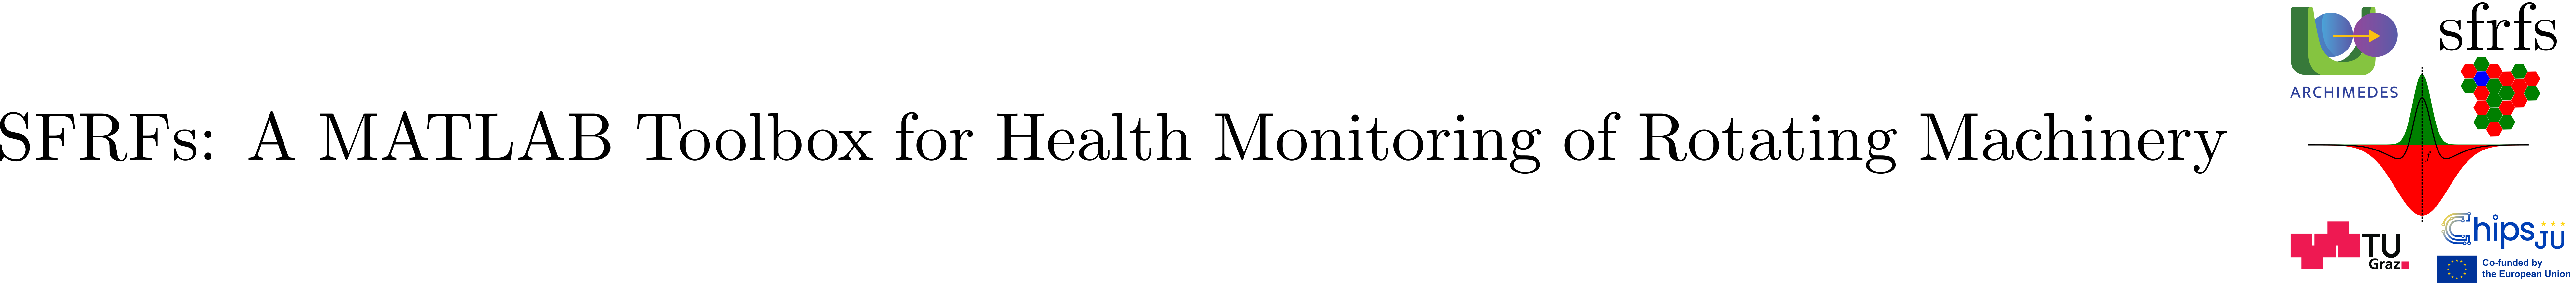

# SFRFsCompute

## Summary

`SFRFsCompute` performs Spectral Fault Receptive Field (SFRF) computations on either time-domain or frequency-domain signal snapshots. It combines snapshot parameters with precomputed receptive field gain functions to evaluate fault-sensitive responses under specified operating conditions.

**Key features**

- Implements Spectral Fault Receptive Fields (SFRFs) as a frequency-domain center–surround operation

- Accepts either time-domain input (via FFT) or precomputed spectra, enforcing mutual exclusivity

- Selects gain functions based on matching operating conditions (Speed, Load)

- Applies center and surround gain masks to spectral content per fault type

- Supports multi-signal (column-wise) processing

- Returns a traceable table preserving fault metadata

- Ensures frequency-domain consistency via `ParametersSnapshot`

- Fully compatible with `ReceptiveFieldGainFunctions` and `FaultFrequencyBands`

### `Description`

The `SFRFsCompute` class provides the numerical execution layer for Spectral Fault Receptive Fields (SFRFs, see Reference [1]). It combines sampling information, pre-computed fault frequency bands, and receptive field gain functions to evaluate spectral responses for specific operating conditions.

Given either a temporal snapshot or a precomputed spectrum, the class selects the appropriate center and surround gain masks based on the requested operating condition and applies them in the frequency domain. The resulting responses are then aggregated and returned in a structured table that preserves fault type, band definitions, and operating metadata.

This class is intentionally decoupled from any component-specific logic and relies solely on the abstractions provided by `FaultFrequencyBands` and `ReceptiveFieldGainFunctions`. This makes it reusable across different system types and fault models, while ensuring consistency in frequency resolution through `ParametersSnapshot`. 

#### Properties

#### Constructor

Creates a configured `SFRFsCompute` object for performing Spectral Fault Receptive Field computations using predefined snapshot parameters and receptive field gain functions.

**Syntax**

- `sfrfsCalc = SFRFsCompute(snapshotParameters = sp, rfgfs = rfgf)`

**Parameters**

#### Methods

- `compute`

Computes SFRFs responses for a given operating condition using either a temporal snapshot or a precomputed spectrum.

**Syntax**

- `responseTable = compute(obj, operatingCondition = oc)`

- `responseTable = compute(obj, temporalSnapshot = x, operatingCondition = oc)`

- `responseTable = compute(obj, spectrumSnapshot = X, operatingCondition = oc)`

Exactly **one** of `temporalSnapshot` or `spectrumSnapshot` **must** be provided. Providing both or neither will raise an error.

`Parameters`

**Output**

**Notes**

- Frequency discretisation is derived from `ParametersSnapshot`.

- Fault selection is performed by matching `Speed` and `Load` in `rfgfsTable`.

- `compute` is side-effect free and returns its result as an independent table.

**See also**

[`ParametersSnapshot`](matlab:open('./ParametersSnapshot.mlx')), [`ReceptiveFieldGainFunctions`](matlab:open('./ReceptiveFieldGainFunctions.mlx'))

## Example

% Define signal and snapshot parameters
fs = 25.6e3;
N  = 32768;
x  = rand(N,1);   % replace with actual vibration signal

paramsSnapshot = ParametersSnapshot( ...
    'samplingFrequency', fs, ...
    'duration', N / fs, ...
    'stride', 1);

% Bearing params
bearingParams = ParametersRollingBearings( ...
    'NumRollingElements', 8, ...
    'BallDiameter',       7.92, ...
    'PitchDiameter',       34.55, ...
    'ContactAngle',       0);

% SFRFs params
sharedParams = SFRFsParameters.createSFRFsParameters( ...
    'order',            0, ...
    'numSidebands',     0, ...
    'numHarmonics',     10, ...
    'sigmaCenter',      [5, 7], ...
    'sigmaSurround',    [12, 3], ...
    'inhibitionFactor', 0.6);

sfrfsParams = SFRFsParametersRollingBearings( ...
    'SameForAllFaultTypes', sharedParams);

% Operating condition
speed = 35;  % Hz
load  = 12;  % N

oc = OperatingConditions(speed, load);

% Fault frequency bands
bfb = BearingFrequencyBands( ...
    bearingParams      = bearingParams, ...
    sfrfsParams         = sfrfsParams, ...
    operatingConditions = oc);

bfb.computeBands();

% RFGFs
rfgfs = ReceptiveFieldGainFunctions(bfb);
f     = paramsSnapshot.getFrequencyDomain();
rfgfs.computeGainFunctions(f);

% SFRF computation

sfrfsCompute = SFRFsCompute( ...
    snapshotParameters = paramsSnapshot, ...
    rfgfs              = rfgfs);


responseTable = sfrfsCompute.compute( ...
    temporalSnapshot  = x, ...
    operatingCondition = oc.conditionsTable);

disp(responseTable)

    FaultGroup       Description        Speed    Load    FrequencyBankMasks       SFRFs   
    __________    __________________    _____    ____    __________________    ___________

        1         "Outer Race Fault"     35       12        {1×1 struct}       {[-0.0305]}
        2         "Inner Race Fault"     35       12        {1×1 struct}       {[-0.0290]}
        3         "Ball Fault"           35       12        {1×1 struct}       {[-0.0309]}
        4         "Cage Fault"           35       12        {1×1 struct}       {[-0.0294]}



`The response table` contains one row per fault type (outFor more detailser race, inner race, ball, and cage), preserving all fault metadata and the corresponding SFRF response value for the specified operating condition.

## API documentation

### MATLAB help

help SFRFsCompute

  SFRFsCompute Performs spectral fault receptive field computations
    Uses ReceptiveFieldGainFunctions (with nested FaultFrequencyBands) and
    ParametersSnapshot to compute responses on input signals.
 
  Example usage:
    sfrfsCalc = SFRFsCompute(paramsSnapshot, rfgfInstance);
    responseTable = sfrfsCalc.compute(x, operatingCondition);

    Documentation for SFRFsCompute
       doc SFRFsCompute




### MATLAB documentation

doc SFRFsCompute

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

Source code for the class can be found in [SFRFsCompute](matlab:open('../../SFRFsCompute.m')).

## Test

Unit testing for the class is implemented in [TestSFRFsCompute](matlab:open('../../../tests/TestSFRFsCompute.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestSFRFsCompute');

Running TestSFRFsCompute
..
Done TestSFRFsCompute
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestSFRFsCompute/testSingleSignalAgainstDoG                                      | Passed
TestSFRFsCompute/testMultiSignalAgainstDoG                                       | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784)

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).